# Thermodynamics of N-Schlogl

%specify roots
roots = [ 1 2 5 8 13]

roots =      1     2     5     8    13


%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end

poly_func = matlabFunction(poly)

poly_func = function_handle with value:
    @(x)-(x-1.0).*(x-2.0).*(x-5.0).*(x-8.0).*(x-1.3e+1)


%Get rate cosntants 
C = coeffs(poly)

$$C = \left(\begin{array}{cccccc} 1040 & -1978 & 1199 & -289 & 29 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccccc} 1040 & 1978 & 1199 & 289 & 29 & 1 \end{array}\right)$$

%get forward and backward rates
rplus = 0;
rmin = 0;

for i = 1:size(k_const,2)
    if mod(i,2) == 0
        rmin = rmin + k_const(i)*x^(i-1);
    else 
        rplus = rplus + k_const(i)*x^(i-1);
    end
end
rpoly = rplus - rmin;

%verify rate from roots and rate cosntants is the same
simplify(rpoly-poly)

$$ans = 0$$

%rate across each reaction
r_rxn = [];
%potential change across each reaction
G_rxn = [];

for i = 1:size(k_const,2)/2
     r_rate = k_const(2*i - 1)*x^(2*i-2) -  k_const(2*i)*x^(2*i-1);
    r_rxn = [r_rxn; r_rate];
    G_rxn = [G_rxn; log(rmin/rplus)*r_rate];
end
r_rxn

$$r\_rxn = \left(\begin{array}{c} 1040-1978\,x\\ 1199\,x^{2}-289\,x^{3}\\ 29\,x^{4}-x^{5} \end{array}\right)$$

G_rxn

$$G\_rxn = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\,\left(1978\,x-1040\right)\\ \sigma_{1}\,\left(1199\,x^{2}-289\,x^{3}\right)\\ \sigma_{1}\,\left(29\,x^{4}-x^{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{x^{5}+289\,x^{3}+1978\,x}{29\,x^{4}+1199\,x^{2}+1040}\right) \end{array}$$

r_rxn_func = matlabFunction(r_rxn)

r_rxn_func = function_handle with value:
    @(x)[x.*-1.978e+3+1.04e+3;x.^2.*1.199e+3-x.^3.*2.89e+2;x.^4.*2.9e+1-x.^5]


G_rxn_func = matlabFunction(G_rxn)

G_rxn_func = function_handle with value:
    @(x)[-log((x.*1.978e+3+x.^3.*2.89e+2+x.^5)./(x.^2.*1.199e+3+x.^4.*2.9e+1+1.04e+3)).*(x.*1.978e+3-1.04e+3);log((x.*1.978e+3+x.^3.*2.89e+2+x.^5)./(x.^2.*1.199e+3+x.^4.*2.9e+1+1.04e+3)).*(x.^2.*1.199e+3-x.^3.*2.89e+2);log((x.*1.978e+3+x.^3.*2.89e+2+x.^5)./(x.^2.*1.199e+3+x.^4.*2.9e+1+1.04e+3)).*(x.^4.*2.9e+1-x.^5)]


%total dissipation
diss = log(rmin/rplus)*poly;
diss_func = matlabFunction(diss);

%plots
x_arr = max(0,min(roots)):abs(min(roots))/10: max(abs(roots));

%rate plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,r_rxn_func(x_arr))
end
plot(x_arr,poly_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×4 string array
    "1"    "2"    "3"    "total"


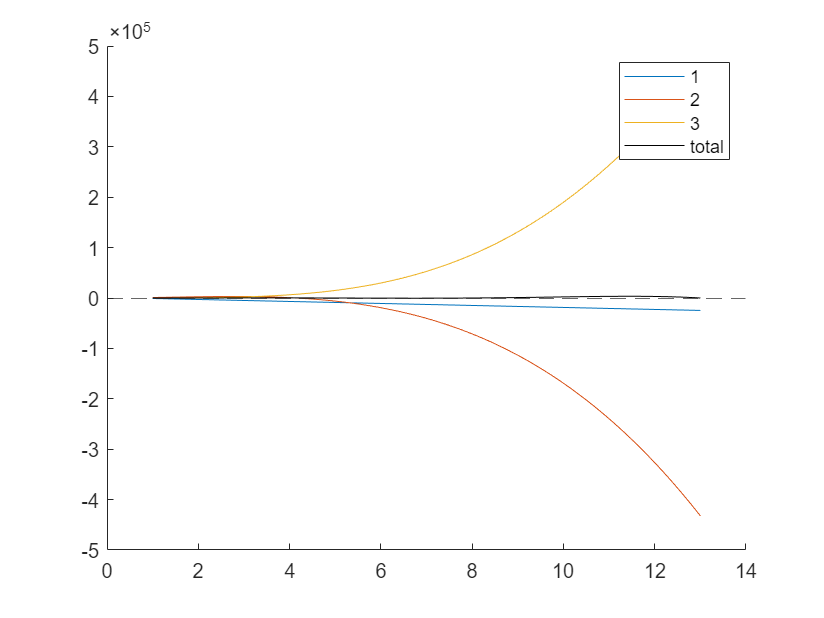

legend(string(label_lst))

%dissipation plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,G_rxn_func(x_arr))
end
plot(x_arr,diss_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×4 string array
    "1"    "2"    "3"    "total"


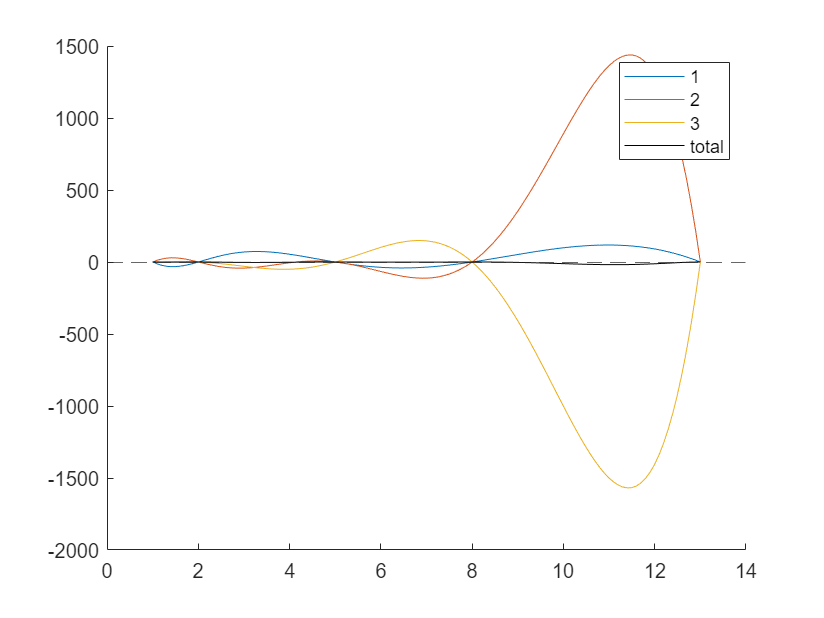

legend(string(label_lst))

label_lst = 1:size(r_rxn,1)

label_lst =      1     2     3
